# Aula 9 - Laboratório de Controle - 2021/1

# Projeto do controlador avanço-atraso para o motor CC

## Nome: Arthur Lorencini Bergamaschi

turma=2 ;
I=1 ;
Tempo=3;

M=[5 9 3 4 1 2 12 7 11 10 8 6
     2 4 5 11 10 1 9 8 7 3 6 12
     9 1 12 8 5 11 6 3 2 4 10 7
     7 6 9 2 11 5 8 4 3 10 12 1
    12 9 3 11 7 8 5 2 10 1 6 4]';

wn=M(I,turma);

arquivo='aula9_R2019.slx';  

load dados.mat
i=wn*50;
ind=(i-20):(i+35);
y1=y1(ind);
u1=u1(ind);
t1=t1(ind);
Ref=mean(y1(end-10:end));
u0=mean(u1(1:10));

## Atividade 0 - Estimação da FT

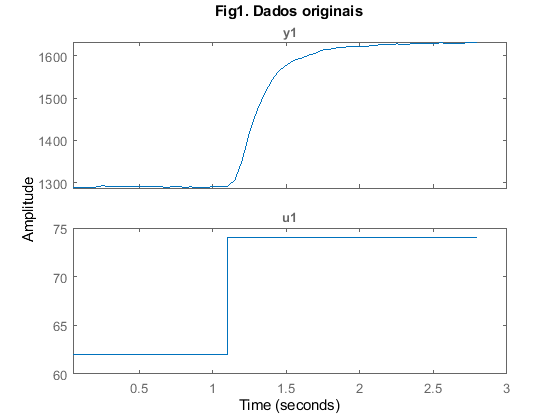

dat=iddata(y1,u1,Ts);
dat_1=iddata(y1-y1(1),u1-u1(1),Ts);
figure
plot(dat);title('Fig1. Dados originais');

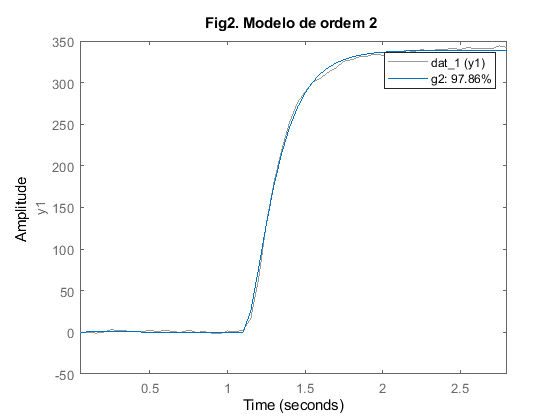

g2=tfest(dat_1,2,0);
g2=tf(g2.Numerator,g2.Denominator);
K=freqresp(g2,0);
compare(dat_1,g2);title('Fig2. Modelo de ordem 2 ');

s=stepinfo(g2);
ts_ma=s.SettlingTime

ts_ma = 0.7316

Ts=0.01;

## Atividade 1 - Obtenção das especificações em frequência a partir do tempo

Na atividade 3 do relatório 8, o melhor PID gerou um bom valor de UP e ts. Como no relatório 7, um modelo de referência é gerado com UP e ts, para obter as especificações em frequência.

UPe=2;
tse=0.5;
a=log(UPe/100);
zeta=sqrt(a^2/(pi^2+a^2));
wn=4/(tse*zeta);
gma=tf(wn^2,[1 2*zeta*wn 0]);
m=tf(wn^2,[1 2*zeta*wn wn^2]);
[~,MFe]=margin(gma);
BWe=bandwidth(m);
Mpe=20*log10(max(bode(m)));
UP=UPe;ts=tse;MF=MFe;BW=BWe;Mp=Mpe;
Tipo={'Especificacoes'};
Tabela1=table(Tipo,UP,ts,MF,BW,Mp)

Tabela1 = 1×6 table
           Tipo           UP    ts       MF        BW          Mp     
    __________________    __    ___    ______    ______    ___________

    {'Especificacoes'}    2     0.5    68.998    9.2048    -0.00017815


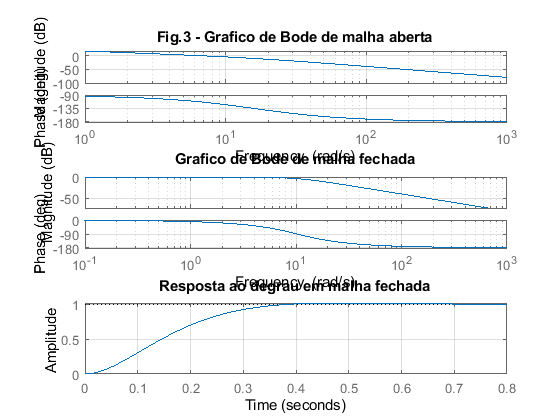

subplot(3,1,1);bode(gma);title('Fig.3 - Grafico de Bode de malha aberta');grid
subplot(3,1,2);bode(m);title('Grafico de Bode de malha fechada');grid
subplot(3,1,3);step(m);title('Resposta ao degrau em malha fechada');grid

1.1 Como garantir o atendimento das especificações no tempo usando as especificações em frequência?

Sabemos que estas especificações já foram atendidas quando definimos as especificações em frequência. Os parâmetros em frequência já são buscados para satisfazer as condições do tempo

## Atividade 2 - Projeto do controlador Atraso

O gráfico de Bode de malha aberta mostrado na Figura 4 já tem o efeito do ganho para atender o erro em regime.

2.1 Qual deve ser o aumento  da margem de fase para alcançar a margem de fase especificada? 

Observando o gráfico de malha aberta, vemos que a margem de fase é de -111° - (-180°) = 69°. Como ela é muito próxima do valor  Encontrado da tabela 1, não vamos ter aumento na margem de fase para alcançar a margem especificada.

Erro_reg=0.01; % Erro percentual de 1%
K1=(1/Erro_reg-1)/K

K1 = 3.5050

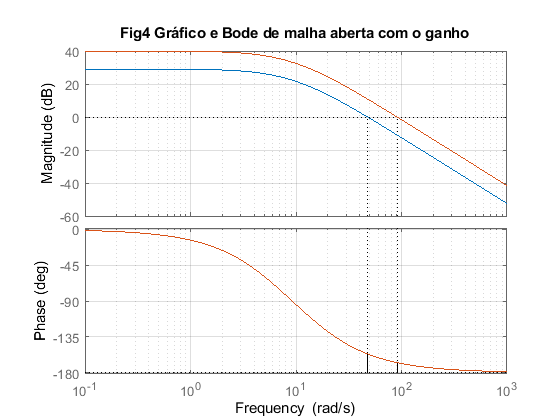

figure
margin(g2);hold on;
margin(K1*g2); grid; title('Fig4 Gráfico e Bode de malha aberta com o ganho'); hold off

2.2 Escolha um valor de MFd para o projeto do controlador atraso de fase, explicando seu efeito no diagrama de Bode (Fig.5) e na resposta ao degrau (Fig.6)

O controlador de atraso de fase tem o efeito de 'puxar' a curva de módulo para frequências menores, ou seja, ela faz com que a frequência de corte nova seja na margem de fase que o usuário quiser. Como adicionamos mais um polo e mais um zero por causa do controlador,

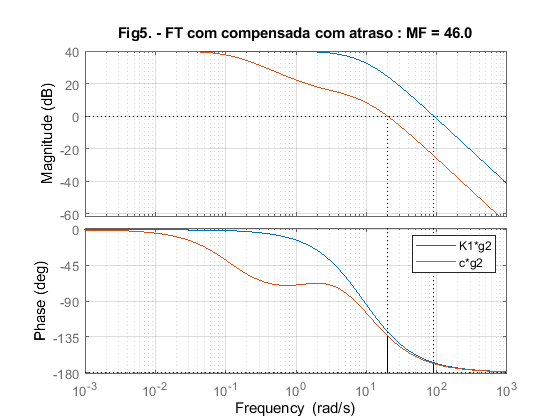

MFd=50;
[c,at]=projat(g2,K1,MFd);

margin(K1*g2);hold on;margin(c*g2);legend('K1*g2','c*g2');grid; hold off
[~,MF1]=margin(c*g2);
str = sprintf('Fig5. - FT com compensada com atraso : MF = %.1f',floor(MF1));
title(str);

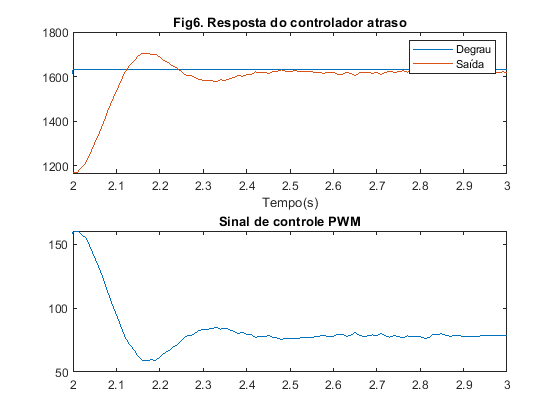

Ts=0.01; 
a=at(1);
T=at(2);
Nc=[a*T 1];
Dc=[T 1];

[Y,t]=simula_slx(arquivo,Tempo);
subplot(2,1,1);plot(t,Y(:,[1,3]));legend('Degrau','Saída');xlabel('Tempo(s)');
title('Fig6. Resposta do controlador atraso');
xlim([2 Tempo]);
subplot(2,1,2);plot(t,Y(:,2));title('Sinal de controle PWM');
xlim([2 Tempo]);


[erro1,UP1,SettlingTime1,iae,G2] = desempenho(Y(:,2:3),t,Ref,2);
m1=feedback(c*g2,1);
[mag,~,w]=bode(m1);
mag=20*log10(squeeze(mag));
BW1=bandwidth(m1);Mp1=20*log10(max(bode(m1)));
UP=[UPe;UP1];ts=[tse;SettlingTime1];MF=[MFe;MF1];BW=[BWe;BW1];Mp=[Mpe;Mp1];
Tipo={'Especificado';'Atraso'};
Tabela2=table(Tipo,UP,ts,MF,BW,Mp)

Tabela2 = 2×6 table
          Tipo           UP        ts         MF        BW          Mp     
    ________________    _____    _______    ______    ______    ___________

    {'Especificado'}        2        0.5    68.998    9.2048    -0.00017815
    {'Atraso'      }    20.04    0.38305    46.392    31.401         2.0734


2.3 Verifique as melhorias conseguidas em MF, BW e Mp com o controlador avanço, analisando a tabela 2.

Analisando a tabela 2, observamos que a largura de banda e o MP aumentaram de valor em comparação com o especificado. Estes valores maiores do que os especificados fazem o sistema agir de forma mais rápida e levemente mais instável. O valor de MF no caso de atraso implica também que o sistema é mais instável do que o especificado.

2.4 Qual o efeito de aumentar MFd sobre UP e ts ?

Se a margem de fase for aumentada, deixamos o sistema mais estável, implicando em baixo UP e alto ts, pois a resposta do sistema seria mais 'sluggish', lerda.

## Atividade 3 - Projeto do controlador Avanço

Escolha a fase fi a adicionar a MF e projetar o controlador avanço.

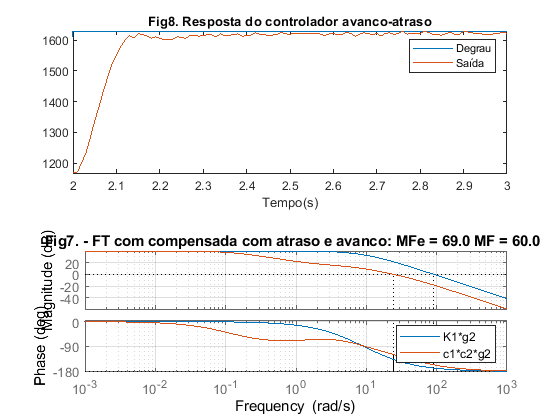

fi=22;
c1=c;
[c2,at]=projav(c1*g2,1,fi);
a=at(1);
T=at(2);
Nc=conv(Nc,[a*T 1]);
Dc=conv(Dc,[T 1]);

margin(K1*g2);hold on;margin(c1*c2*g2);legend('K1*g2','c1*c2*g2');grid; hold off
m2=feedback(c1*c2*g2,1);BW2=bandwidth(m2);MP2=20*log10(max(bode(m2)));
[~,MF2]=margin(c1*c2*g2);
str = sprintf('Fig7. - FT com compensada com atraso e avanco: MFe = %.1f MF = %.1f ',MFe,floor(MF2));
title(str);

[Y,t]=simula_slx(arquivo,Tempo);
subplot(2,1,1);plot(t,Y(:,[1,3]));legend('Degrau','Saída');xlabel('Tempo(s)');
title('Fig8. Resposta do controlador avanco-atraso');
xlim([2 Tempo]);

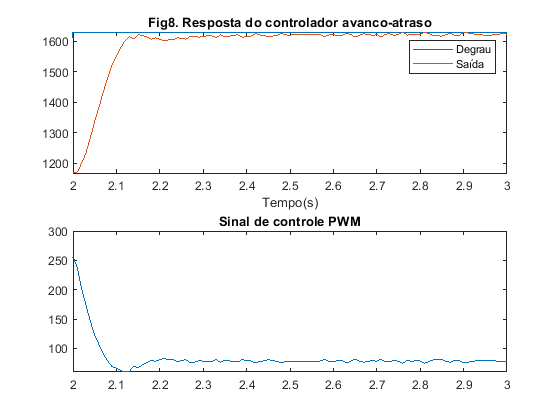

subplot(2,1,2);plot(t,Y(:,2));title('Sinal de controle PWM');
xlim([2 Tempo]);

3.1 Explique como escolher MFd e fi para atender as especificações. 

Para atender as especificações, o MFd precisa ser menor do que o valor especificado e o valor de fi deve ser tal que a soma de MFd e fi dê próximo do MFe. Como já foi escolhido o valor de MFd igual à 50, vamos escolher fi igual à 22 para dar próximo de 70, que é o valor perto de MFe.

[erro2,UP2,SettlingTime2] = desempenho(Y(:,2:3),t,Ref,2);
UP=[UPe;UP1;UP2];ts=[tse;SettlingTime1;SettlingTime2];MF=[MFe;MF1;MF2];BW=[BWe;BW1;BW2];Mp=[Mpe;Mp1;MP2];
Tipo={'Especificacoes';'Atraso';'Avanco-atraso'};
Erro=[100*Erro_reg;erro1;erro2];
Tabela3=table(Tipo,UP,ts,MF,BW,Mp,Erro)

Tabela3 = 3×7 table
           Tipo             UP         ts         MF        BW          Mp          Erro  
    __________________    _______    _______    ______    ______    ___________    _______

    {'Especificacoes'}          2        0.5    68.998    9.2048    -0.00017815          1
    {'Atraso'        }      20.04    0.38305    46.392    31.401         2.0734     0.5719
    {'Avanco-atraso' }    0.67413    0.13329    60.833    38.458       0.028435    0.45778


3.2 Comentar atendimento das especificações em frequência, com valores dos gráficos e da Tabela 3.

Analisando os valores da tabela 3, observamos que o sistema de avanço-atraso se comporta melhor do que o 'atraso', pois temos uma sobreelevação quase nula, um tempo de estabelecimento muito curto, de 0.13s, uma margem de fase boa, de 38°, implicando em um sistema estável e um erro menor, de 0.57 para 0.45. Uma frequência maior de banda, de 31 para 38, também implica em uma resposta mais rápida. 

3.3 Compare o projeto do PID com o do avano-atraso em relação a: a) erro em regime b) Dificuldades para fazer o projeto em duas etapas (PI depois PD ou atraso e depois avanço) c) Uso de especificações no tempo ou frequência

A) O PID leva vantagem no quesito erro em regime, pois o erro em regime do PID é nulo para todos os casos. Já no caso do 'avanço-atraso', temos um erro de 0.4%

B) No quesito dificuldade, o PID é o mais complicado, pois precisa de uma série de ferramentas, como o rlocus, sisotool, várias análises, testes de posição de zero e de pólo que, dependendo da quantidade de parâmetros, pode complexar demais a solução. Para o caso do 'avanço-atraso', usou-se apenas algumas rotinas e análises do gráfico de bode para definir um bom controlador, ou seja, bem menos dificultoso.

C) Como dito no início do relatório, para o caso do avanço-atraso, as especificações da frequência são obtidas já satisfazendo o que é desejado no domínio do tempo. Para o caso do projeto PID, testa-se alguns valores iniciais na frequência para checar se os valores no tempo serão satisfeitos.

datetime('now')

ans = datetime
   18-Aug-2021 21:20:25


pwd

ans = 'C:\Users\malaquias\Desktop\UFES\UFES-LCA\Original\Aula9'